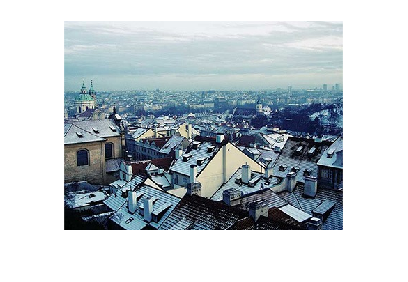

cosine_matrix = [0.3536 0.3536 0.3536 0.3536 0.3536 0.3536 0.3536 0.3536;
    0.4904 0.4157 0.2778 0.0975 -0.0975 -0.2778 -0.4157 -0.4904;
    0.4619 0.1913 -0.1913 -0.4619 -0.4619 -0.1913 0.1913 0.4619;
    0.4157 -0.0975 -0.4904 -0.2778 0.2778 0.4904 0.0975 -0.4157;
    0.3536 -0.3536 -0.3536 0.3536 0.3536 -0.3536 -0.3536 0.3536;
    0.2778 -0.4904 0.0975 0.4157 -0.4157 -0.0975 0.4904 -0.2778;
    0.1913 -0.4619 0.4619 -0.1913 -0.1913 0.4619 -0.4619 0.1913;
    0.0975 -0.2778 0.4157 -0.4904 0.4904 -0.4157 0.2778 -0.0975;
    ];

quantization = [16 11 10 16 24 40 51 61;
                12 12 14 19 26 58 60 55;
                14 13 16 24  40 57 69 56;
                14 17 22 29 51 87 80 62;
                18 22 37 56 68 109 103 77;
                24 35 55 64 81 104 113 92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103 99;];

block_size = 8;

compression_ratio = 20;

quantization = quantization * compression_ratio;


old_img = imread("C:\Users\91630\OneDrive\Documents\sample4.jpg");
imshow(old_img);


old_img = double(old_img);

[size1,size2,size3] = size(old_img)

size1 = 300

size2 = 400

size3 = 3


rows = size1;
columns = size2;

k1 = rem(size1,8)

k1 = 4

k2 = rem(size2,8)

k2 = 0


if k1~=0
    rows = size1 + 8-k1
end

rows = 304

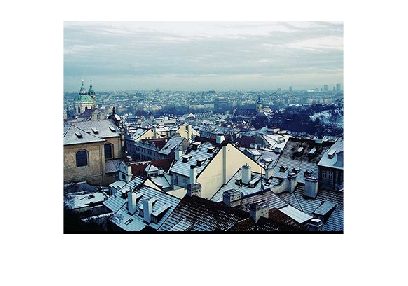


if k2~=0
    columns=size2+8-k2
end

i =1;
j = 1;
img = zeros(rows,columns,3);
while logical(rem(1,2))
    if i>size1
        break;
    end
    j = 1;
    while logical(rem(1,2))
       if j>size2 
           break;
       end
            img(i,j,1)=old_img(i,j,1);
            img(i,j,2)=old_img(i,j,2);
            img(i,j,3)=old_img(i,j,3);
            j = j+1;
    end
     i = i+1;
end

imshow(uint8(img))



R_channel_img = img(:,:,1) ;

number_of_horizontal_blocks = columns/8

number_of_horizontal_blocks = 50


number_of_vertical_blocks = rows/8

number_of_vertical_blocks = 38



flag = 1; % up
encoded1 = zeros(1);
encoded1 = [];




i = 1;
j = 1;
while i<=number_of_vertical_blocks
    j = 1;
   
    while j<=number_of_horizontal_blocks
         x=1;
        y =1;
        eight_cross_eight_block = R_channel_img(8*i-7:8*i,8*j-7:8*j);

        m = eight_cross_eight_block - 128;


dct = cosine_matrix*m*cosine_matrix';

quantizied = round(dct./quantization);

%encoding

while logical(rem(1,2))
    
     if x == block_size && y==block_size+1
         break;
     elseif x == block_size+1 && y == block_size
             break;
     elseif x==block_size&&y==block_size
         encoded1 = [encoded1 quantizied(x,y)];
         break;
     end

    
     encoded1 = [encoded1 quantizied(x,y)];
   

    if y == block_size && flag == 1
        x = x +1;
        flag = 0;
    elseif x==1 && flag == 1 
        y = y+1;
        flag = 0;
    elseif flag == 1
        x = x-1;
        y = y+1;
    elseif x==block_size && flag ==0
        y = y+1;
        flag = 1;
    elseif y==1 && flag == 0
        x = x+1;
        flag =1;
    elseif flag == 0
        x = x+1;
        y = y-1;
    end

end

l = length(encoded1);

while logical(rem(1,2))
    if l==0 || encoded1(l) ~= 0
        break;
    elseif encoded1(l) == 0
        encoded1(l) = [];
     l = l-1;
    end
end




j = j+1;
 encoded1 = [encoded1 -100];

    end
    i = i +1;
end

encoded1

encoded1 =      2  -100     2  -100     2  -100     2  -100     2  -100     2  -100     2  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100




G_channel_img = img(:,:,2);




number_of_horizontal_blocks = columns/8

number_of_horizontal_blocks = 50


number_of_vertical_blocks = rows/8

number_of_vertical_blocks = 38


flag = 1; % up
encoded2 = zeros(1);
encoded2 = [];




i = 1;
j = 1;
while i<=number_of_vertical_blocks
    j = 1;
   
    while j<=number_of_horizontal_blocks
         x=1;
        y =1;
        eight_cross_eight_block = G_channel_img(8*i-7:8*i,8*j-7:8*j);

        m = eight_cross_eight_block -128;

dct = cosine_matrix*m*cosine_matrix';

quantizied = round(dct./quantization);

%encoding

while logical(rem(1,2))
    
     if x == block_size && y==block_size+1
         break
     elseif x == block_size+1 && y == block_size
             break
     elseif x==block_size&&y==block_size
         encoded2 = [encoded2 quantizied(x,y)];
         break;
     end

    
     encoded2 = [encoded2 quantizied(x,y)];
   

    if y == block_size && flag == 1
        x = x +1;
        flag = 0;
    elseif x==1 && flag == 1 
        y = y+1;
        flag = 0;
    elseif flag == 1
        x = x-1;
        y = y+1;
    elseif x==block_size && flag ==0
        y = y+1;
        flag = 1;
    elseif y==1 && flag == 0
        x = x+1;
        flag =1;
    elseif flag == 0
        x = x+1;
        y = y-1;
    end

end

l = length(encoded2);
while logical(rem(1,2))
    if l==0 || encoded2(l) ~= 0
        break;
    elseif encoded2(l) == 0
        encoded2(l) = [];
        l = length(encoded2);
    end
end




j = j+1;
 encoded2 = [encoded2 -100];

    end
    i = i +1;
end


encoded2

encoded2 =      3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100




B_channel_img = img(:,:,3);



number_of_horizontal_blocks = columns/8

number_of_horizontal_blocks = 50


number_of_vertical_blocks = rows/8

number_of_vertical_blocks = 38


flag = 1; % up
encoded3 = zeros(1);
encoded3 = [];




i = 1;
j = 1;
while i<=number_of_vertical_blocks
    j = 1;
   
    while j<=number_of_horizontal_blocks
         x=1;
        y =1;
        eight_cross_eight_block = B_channel_img(8*i-7:8*i,8*j-7:8*j);

        m = eight_cross_eight_block -128;

dct = cosine_matrix*m*cosine_matrix';

quantizied = round(dct./quantization);

%encoding

while logical(rem(1,2))
    
     if x == block_size && y==block_size+1
         break
     elseif x == block_size+1 && y == block_size
             break
     
     elseif x==block_size&&y==block_size
         encoded3 = [encoded3 quantizied(x,y)];
         break;
     end

    
     encoded3 = [encoded3 quantizied(x,y)];
   

    if y == block_size && flag == 1
        x = x +1;
        flag = 0;
    elseif x==1 && flag == 1 
        y = y+1;
        flag = 0;
    elseif flag == 1
        x = x-1;
        y = y+1;
    elseif x==block_size && flag ==0
        y = y+1;
        flag = 1;
    elseif y==1 && flag == 0
        x = x+1;
        flag =1;
    elseif flag == 0
        x = x+1;
        y = y-1;
    end

end

l = length(encoded3);
while logical(rem(1,2))
    if l==0 || encoded3(l) ~= 0
        break;
    elseif encoded3(l) == 0

        encoded3(l) = [];
        l = length(encoded3);
    end
end



j = j+1;
 encoded3 = [encoded3 -100];

    end
    i = i +1;
end


encoded3

encoded3 =      3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100     3  -100
